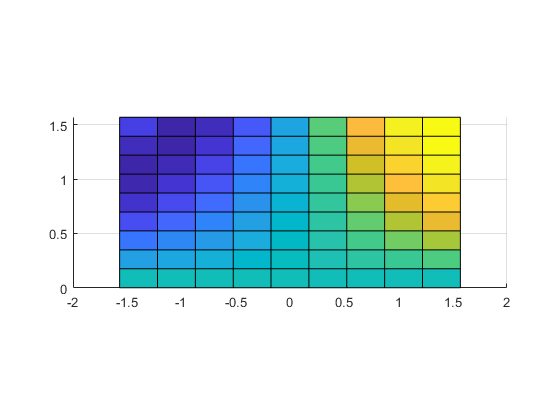

% clear;
% for i = 1:3
%     for j = 1:3
%         for k = 1:5
%             A(i,j,k) = i + 2*j;
%         end
%     end
% end
% 
% A
% 
% B = reshape(A,[],5)

clear;
M = 10;
N = 10;
orig_dom_X1 = linspace(-pi/2,pi/2,M);
orig_dom_Y1 = linspace(0,pi/2,N);
[X,Y] = ndgrid(orig_dom_X1,orig_dom_Y1);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,2))
daspect([1 1 1])
view(2)

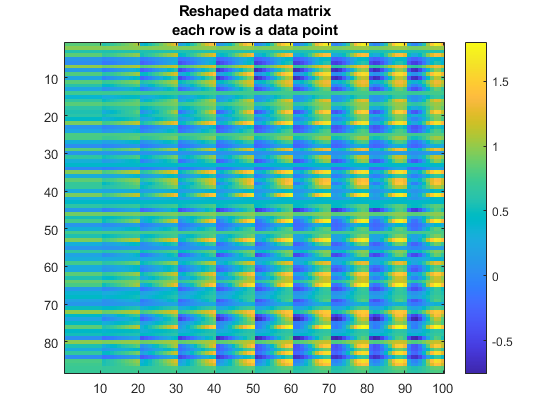


s = size(A);

B = reshape(A,[],s(end));
B = B';
imagesc(B)
colorbar
title(['Reshaped data matrix' newline 'each row is a data point'])

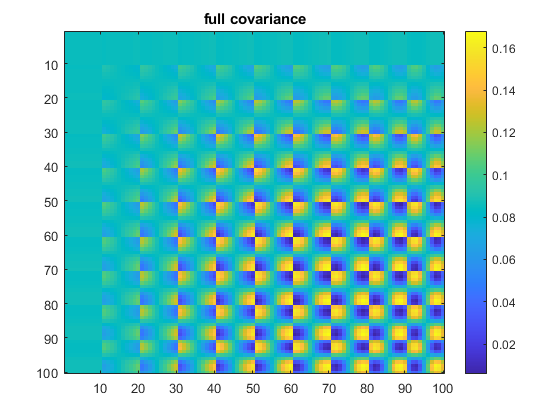


C_B = cov(B);
imagesc(C_B)
colorbar
title('full covariance')

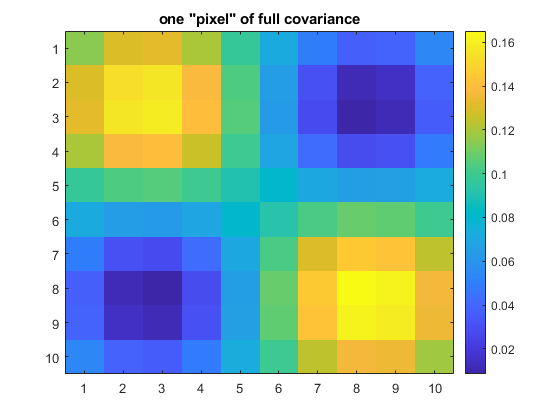


imagesc(C_B((end-M+1):end,(end-M+1):end))
colorbar
title('one "pixel" of full covariance')

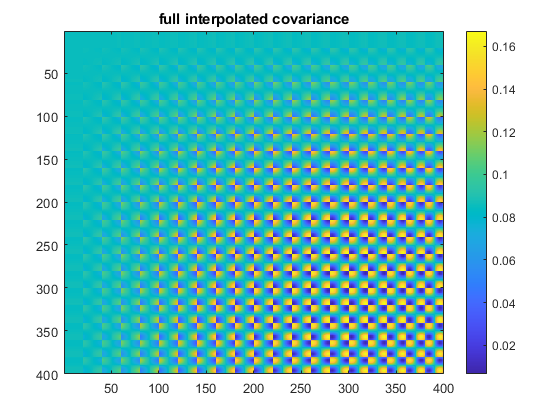


N_h = 20;
M_h = 20;

new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(0,pi/2,N_h);
new_dom_X2 = linspace(-pi/2,pi/2,M_h);
new_dom_Y2 = linspace(0,pi/2,M_h);

[X1_h,Y1_h] = ndgrid(new_dom_X1,new_dom_Y1);
wv_1 = reshape(permute(cat(3,X1_h,Y1_h),[3 1 2]),2,[])';
% disp('size(wv_1,2)')
% size(wv_1,2)

[X2_h,Y2_h] = ndgrid(new_dom_X2,new_dom_Y2);
wv_2 = reshape(permute(cat(3,X2_h,Y2_h),[3 1 2]),2,[])';
% disp('size(wv_2,2)')
% size(wv_2,2)

C_B_high_def = covariance_function(wv_1,wv_2,orig_dom_X1,orig_dom_Y1,C_B);

imagesc(C_B_high_def)
colorbar
title('full interpolated covariance')

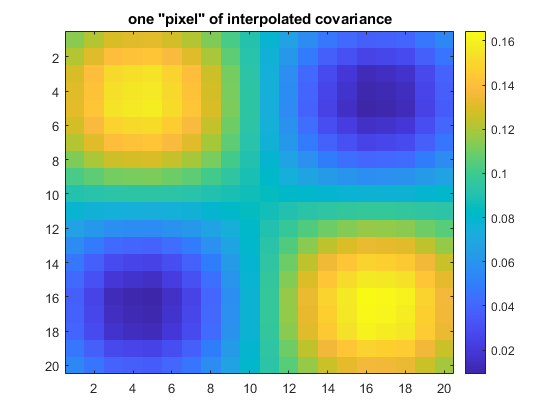


imagesc(C_B_high_def((end-N_h+1):end,(end-M_h+1):end))
colorbar
title('one "pixel" of interpolated covariance')